# 802.11ac SEM (dB scale)

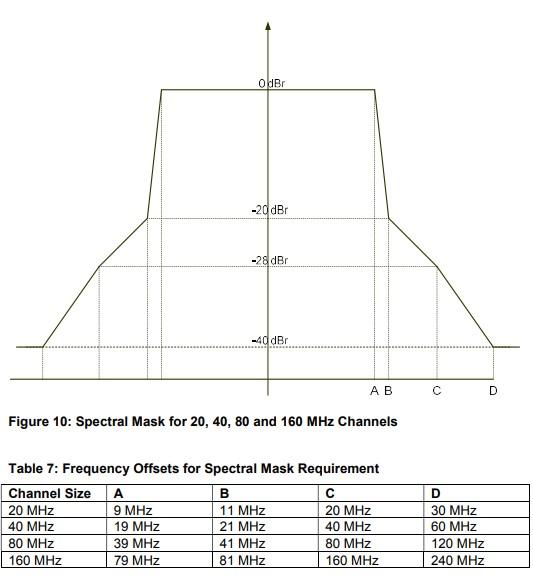

### Normalized frequency $fT_s=\frac{f}{f_s}\in [-0.5, 0.5]$

### Definition of the 20 Mhz 802.11ac SEM function in $f$ (MHz)


$$\mathrm{SEM}(f) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |f| \leq 9\\
-10 |f| + 90 & \mbox{if } \quad 9\leq |f| \leq 11\\
-\frac{8}{9} |f| +(\frac{88}{9}-20) & \mbox{if } \quad 11\leq |f| \leq 20\\
-\frac{6}{5} |f| - 4 & \mbox{if } \quad 20\leq |f| \leq 30\\
-40 & \mbox{if } \quad |f| \geq 30\\
\end{array}\right.$$


### Definition of the 802.11ac SEM in $f, f_s
$ (MHz)


$$\mathrm{SEM}(fT_s, f_s) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |fT_s| \leq \frac{9}{f_s}\\
-10\cdot f_s \cdot |fT_s| + 90 & \mbox{if } \quad \frac{9}{f_s}\leq |fT_s| \leq \frac{11}{f_s}\\
-\frac{8}{9} \cdot f_s \cdot |fT_s|+(\frac{88}{9}-20) & \mbox{if } \quad \frac{11}{f_s}\leq |fT_s| \leq \frac{20}{f_s}\\
-\frac{6}{5} \cdot f_s \cdot |fT_s| - 4 & \mbox{if } \quad \frac{20}{f_s}\leq |fT_s| \leq \frac{30}{f_s}\\
-40 & \mbox{if } \quad |fT_s| \geq \frac{30}{f_s}\\
\end{array}\right.$$


function SEM = SEM_ac(fTs, fs, channel_size)
% Keep only the positive part
fTs = fTs((length(fTs)+1)/2 : end);
SEM = zeros(length(fTs), 1);

fs = 2*fs;

if channel_size == 20   % on_ratio = 0.5485
    for idx = 1:length(fTs)
        if fTs(idx) < 9/fs
            % freq: 0~9 MHz
            SEM(idx) = 0;
        elseif fTs(idx) < 11/fs
            % freq: 9~11 MHz
            SEM(idx) = -10 * (fTs(idx)*fs) + 90;
        elseif fTs(idx) < 20/fs
            % freq: 11~20 MHz
            SEM(idx) = -(8/9) * (fTs(idx)*fs) + (88/9 - 20);
        elseif fTs(idx) < 30/fs
            % freq: 20~30 MHz
            SEM(idx) = -1.2 * (fTs(idx)*fs) - 4;
        else
            % freq: >30 MHz
            SEM(idx) = -40;
        end
    end
elseif channel_size == 40   % on_ratio = 0.4653
    for idx = 1:length(fTs)
        if fTs(idx) < 19/fs
            % freq: 0~19 MHz
            SEM(idx) = 0;
        elseif fTs(idx) < 21/fs
            % freq: 19~21 MHz
            SEM(idx) = -10 * (fTs(idx)*fs) + 190;
        elseif fTs(idx) < 40/fs
            % freq: 21~40 MHz
            SEM(idx) = -(8/19) * (fTs(idx)*fs) + (168/19 - 20);
        elseif fTs(idx) < 60/fs
            % freq: 40~60 MHz
            SEM(idx) = -0.6 * (fTs(idx)*fs) - 4;
        else
            % freq: >60 MHz
            SEM(idx) = -40;
        end
    end
elseif channel_size == 80   % on_ratio = 0.4851
    for idx = 1:length(fTs)
        if fTs(idx) < 39/fs
            % freq: 0~39 MHz
            SEM(idx) = 0;
        elseif fTs(idx) < 41/fs
            % freq: 39~41 MHz
            SEM(idx) = -10 * (fTs(idx)*fs) + 390;
        elseif fTs(idx) < 80/fs
            % freq: 41~80 MHz
            SEM(idx) = -(8/39) * (fTs(idx)*fs) + (328/39 - 20);
        elseif fTs(idx) < 120/fs
            % freq: 80~120 MHz
            SEM(idx) = -0.3 * (fTs(idx)*fs) - 4;
        else
            % freq: >120 MHz
            SEM(idx) = -40;
        end
    end
elseif channel_size == 160  % on_ratio = 0.4851
    for idx = 1:length(fTs)
        if fTs(idx) < 79/fs
            % freq: 0~79 MHz
            SEM(idx) = 0;
        elseif fTs(idx) < 81/fs
            % freq: 79~81 MHz
            SEM(idx) = -10 * (fTs(idx)*fs) + 790;
        elseif fTs(idx) < 160/fs
            % freq: 81~160 MHz
            SEM(idx) = -(8/79) * (fTs(idx)*fs) + (648/79 - 20);
        elseif fTs(idx) < 240/fs
            % freq: 160~240 MHz
            SEM(idx) = -(3/20) * (fTs(idx)*fs) - 4;
        else
            % freq: >240 MHz
            SEM(idx) = -40;
        end
    end
end

% Generate the negative part
SEM = [flipud(SEM); SEM(2:end)];
end